# Demo 1: GLM temporal stimulus

Simulate and fit a single-neuron GLM with 1D (temporal) filter with exponential nonlinearity

% Make sure paths are set (assumes this script called from home directory for the repository)
setpaths_GLMspiketools

### 1. Set parameters and display for GLM 

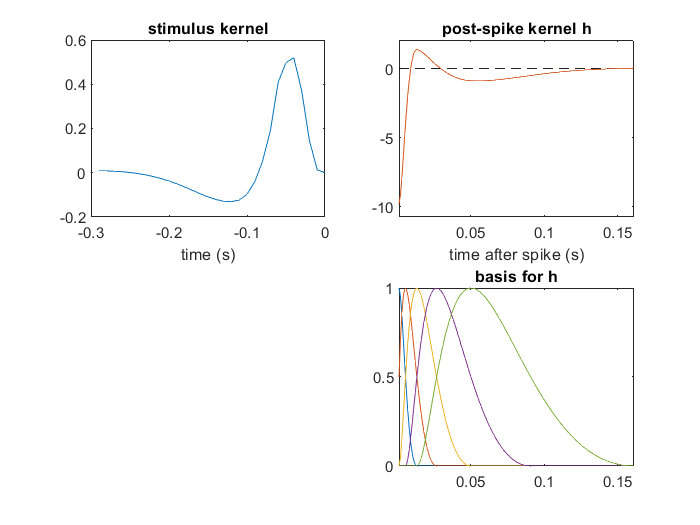

dtStim = 0.01;   % Bin size for stimulus (in seconds).  (Equiv to 100Hz frame rate)
dtSp = 0.001;    % Bin size for simulating model & computing likelihood (must evenly divide dtStim);
nkt = 30;        % Number of time bins in stimulus filter k

% Create GLM structure with default params
ggsim = makeSimStruct_GLM(nkt, dtStim, dtSp); 

% === Plot true model params =======================
figure('name', 'model params')
ttk = dtStim * (-nkt+1:0)';  % time relative to spike of stim filter taps

subplot(221)
plot(ttk, ggsim.k)
title('stimulus kernel')
xlabel('time (s)')

subplot(222); % --------
plot(ggsim.iht, ggsim.iht*0, 'k--', ggsim.iht, ggsim.ih);
title('post-spike kernel h')
axis tight
xlabel('time after spike (s)')
set(gca, 'ylim',[min(ggsim.ih)*1.1 max(ggsim.ih)*1.5])

subplot(224); % --------
[iht, ihbasOrthog, ihbasis] = makeBasis_PostSpike(ggsim.ihbasprs, dtSp);
plot(ggsim.iht, ihbasis)
title('basis for h')
axis tight

### 2. Generate some training data 

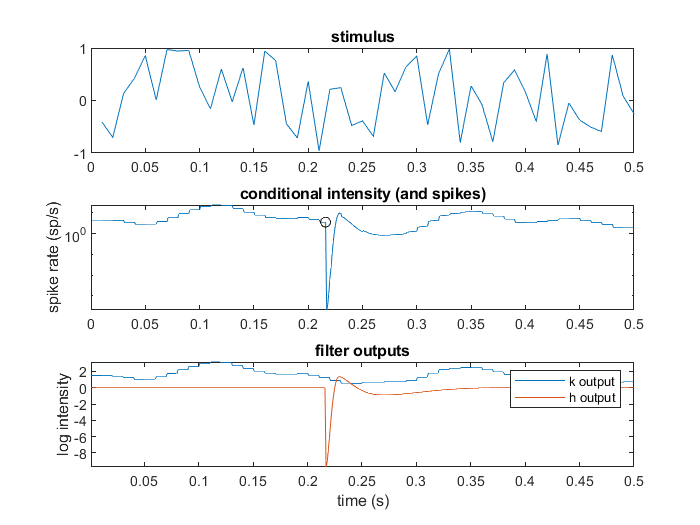

stim_length = 50000;    % Stimulus length (frames); more samples gives better fit
stim_width = 1;         % Stimulus width  (pixels); must match # pixels in stim filter

% Make stimulus
Stim = rand(stim_length, stim_width)*2-1;  % Stimulate model to long, unif-random stimulus

% Simulate model
[~, binary_spike_vector, Itot, Istm] = simGLM(ggsim, Stim); 

% --- Make plot of first 0.5 seconds of data --------
tlen = 0.5;
ttstim = dtStim : dtStim : tlen;
iistim = 1 : length(ttstim);

figure('name','training data')
subplot(311)
plot(ttstim, Stim(iistim))
title('stimulus')

ttspk = dtSp : dtSp : tlen; 
iispk = 1 : length(ttspk);
spinds = binary_spike_vector(iispk) > 0;

subplot(312)
semilogy(ttspk, exp(Itot(iispk)), ttspk(spinds), exp(Itot(spinds)), 'ko')
ylabel('spike rate (sp/s)')
title('conditional intensity (and spikes)')

subplot(313); 
Isp = Itot-Istm; % total spike-history filter output
plot(ttspk,Istm(iispk), ttspk,Isp(iispk))
axis tight
legend('k output', 'h output')
xlabel('time (s)')
ylabel('log intensity')
title('filter outputs')

### 3. Setup fitting params 

% Compute the STA
sps_coarse = sum(reshape(binary_spike_vector,[],stim_length),1)'; % bin spikes in bins the size of stimulus
spike_trig_avg = simpleSTC(Stim,sps_coarse,nkt); 
spike_trig_avg = reshape(spike_trig_avg, nkt, []); % reshape it to match dimensions of true filter

% Set mask (if desired)
exptmask= []; %[1 slen*dtStim];  % data range to use for fitting (in s).

% Set params for fitting, including bases 
nkbasis = 8;  % number of basis vectors for representing k
nhbasis = 8;  % number of basis vectors for representing h
hpeakFinal = .1;   % time of peak of last basis vector for h

gg0 = makeFittingStruct_GLM(dtStim, dtSp, nkt, nkbasis, spike_trig_avg, nhbasis, hpeakFinal);

gg0.sps = binary_spike_vector;  % Insert binned spike train into fitting struct
gg0.mask = exptmask; % insert mask (optional)
gg0.ihw = randn(size(gg0.ihw))*1; % initialize spike-history weights randomly

% Compute conditional intensity at initial parameters 
[negloglival0,rr] = neglogli_GLM(gg0, Stim);
fprintf('Initial negative log-likelihood: %.5f\n', negloglival0);

Initial negative log-likelihood: 195.64805


### 4. Fit using Maximum Likelihood

opts = {'display', 'iter', 'maxiter', 100}; % options for fminunc
[gg1, negloglival] = MLfit_GLM(gg0,Stim,opts); % do ML (requires optimization toolbox)


                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            57.5233                      1.88e+03                
     1            57.5233             10       1.88e+03           6
     2            57.5233            2.5       1.88e+03           0
     3           -1123.48          0.625       1.43e+03           0
     4           -1633.51           1.25       1.15e+03           6
     5           -2011.32           1.25            211           5
     6           -2148.98            2.5             38           6
     7           -2229.39        4.35003           37.4           6
     8           -2245.57        3.17088           11.1           8
     9           -2248.68        2.20946           4.77           8
    10           -2249.24       0.379161            3.3           8
    11            -2249.4       0.263575           2.75           8
    12           -2249.45       0.140923        

## 5. Plot results

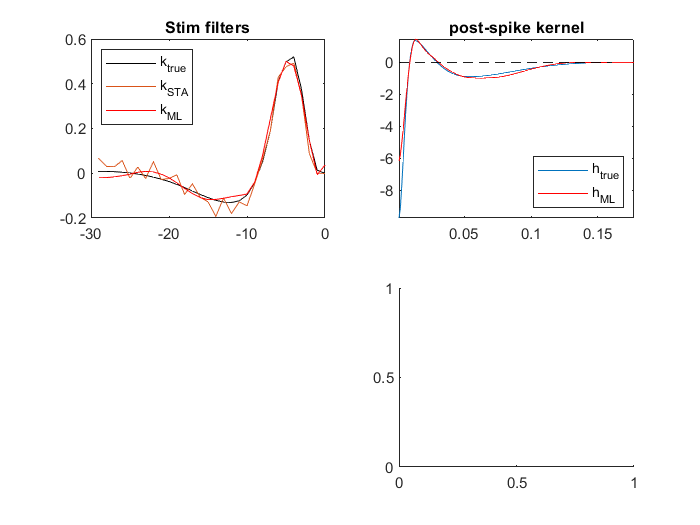

ttk = -nkt+1:0; % time bins for stimulus filter

figure('name','GLM results')

subplot(221);  % True filter 
plot(ttk, ggsim.k, 'k', ttk, spike_trig_avg./norm(spike_trig_avg)*norm(ggsim.k), ttk, gg1.k, 'r');
title('Stim filters');
legend('k_{true}', 'k_{STA}', 'k_{ML}', 'location', 'northwest');

% ----------------------------------
subplot(222); 
plot(ggsim.iht, ggsim.ih, gg1.iht, gg1.ih,'r', ggsim.iht, ggsim.iht*0, 'k--');
title('post-spike kernel');
axis tight;
legend('h_{true}', 'h_{ML}', 'location', 'southeast');
% ----------------------------------
subplot(224); 

plot(ggsim.iht, exp(ggsim.ih), gg1.iht, exp(gg1.ih),'r', ggsim.iht,ggsim.iht*0+1,'k--');
title('exponentiated post-spike kernels');
xlabel('time since spike (s)');
ylabel('gain'); axis tight;
legend('h_{true}', 'h_{ML}', 'location', 'southeast');

% Errors in STA and ML estimate (subspace angle between true k and estimate)
fprintf('Filter estimation error (in radians)\n  sta: %.3f\n   ML: %.3f\n', ...
    subspace(ggsim.k,spike_trig_avg), subspace(ggsim.k,gg1.k));

Filter estimation error (in radians)
  sta: 